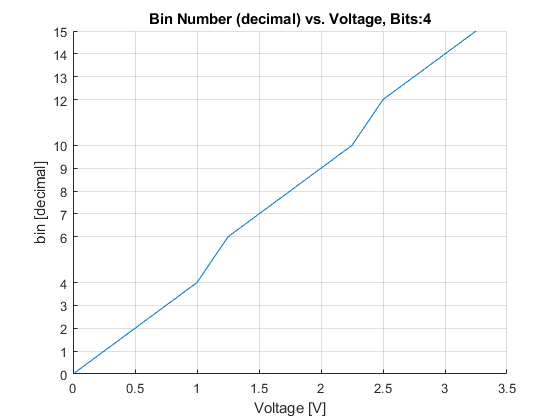

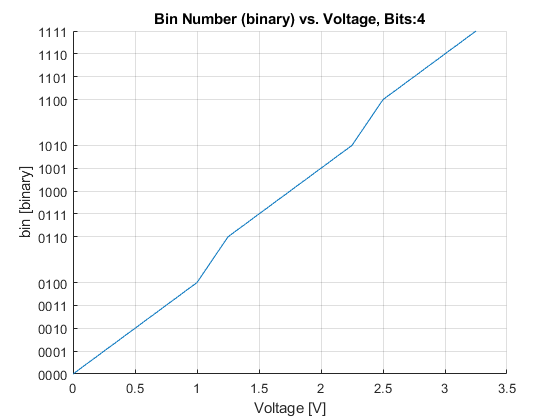

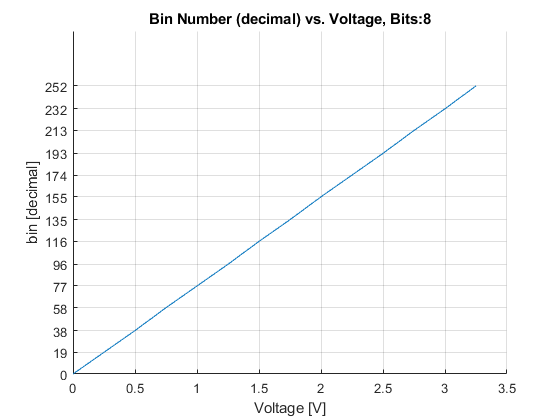

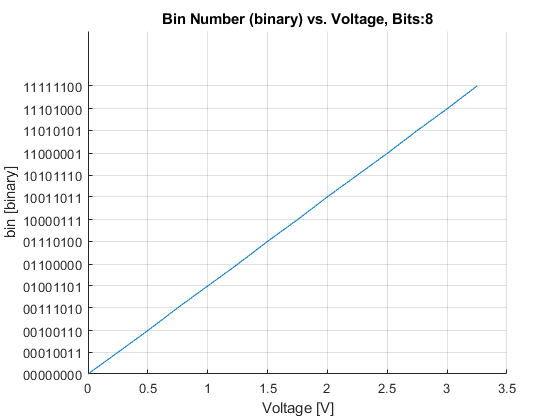

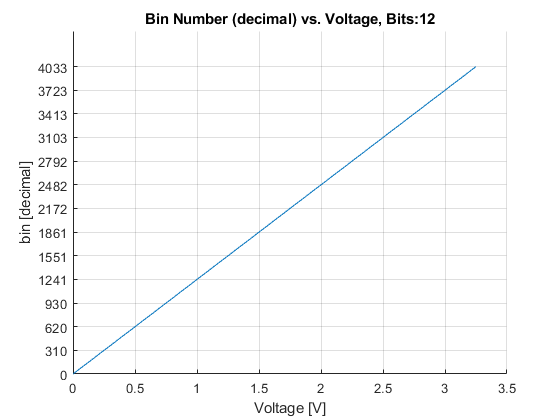

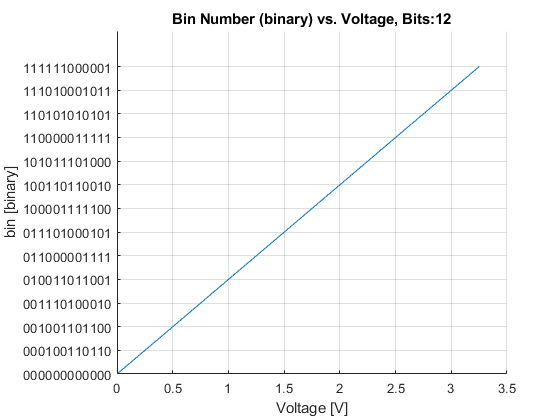

clear;
close all;

% Min & Max Voltages
min_voltage = 0;
max_voltage = 3.3;

% Given Values
voltages = [0 0.25 0.5 0.75 1 1.25 1.5 1.75 2 2.25 2.5 2.75 3 3.25];
bits = [4,8,12];


for i = bits

    figure();
    hold on;
    grid on;
    title(strcat('Bin Number (decimal) vs. Voltage, Bits: ',num2str(i)))
    xlabel('Voltage [V]')
    ylabel('bin [decimal]')
    % Assign Voltages
    for j = 1:length(voltages)
        bin(j) = Voltage2Bin(voltages(j),min_voltage,max_voltage,i);
    end 
    plot(voltages,bin)
    yticks(bin) % Adjust to only show at bins
    
    % Convert from decimal to binary and plot
    bins2binary = dec2bin(bin);
    figure();
    hold on;
    grid on;
    title(strcat('Bin Number (binary) vs. Voltage, Bits: ',num2str(i)))
    yticks(bin)
    yticklabels(bins2binary)
    xlabel('Voltage [V]')
    ylabel('bin [binary]')
    plot(voltages,bin)
end

function [bin] = Voltage2Bin(voltage,min_voltage,max_voltage,bits)

% Voltage Range
range = max_voltage - min_voltage;

% Number of Levels
levels = 2^bits;

% Least Significant Bit
LSB = range/levels;

bin = floor(voltage/LSB);

end